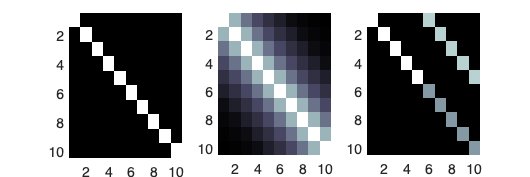

create_figure('autocorr', 1, 3);
colormap bone;

X = eye(10); imagesc(X); set(gca, 'YDir', 'reverse'); axis tight

subplot(1, 3, 2); set(gca, 'YDir', 'reverse'); axis tight
rho = .7; 
X = toeplitz([1 rho rho^2 rho^3 rho^4 rho^5 rho^7 rho^8 rho^9 rho^10]);
imagesc(X);

subplot(1, 3, 3); set(gca, 'YDir', 'reverse'); axis tight
rho = .7; k = .4;
X = diag([1 1 1 1 1 .6 .6 .6 .6 .6]);
X = X + diag([.8 .8 .8 .8 .8], 5);
imagesc(X);

n = 200;    % number of time points

rho = 0.5;  % rho autocorrelation param for AR(1) model 
% e(i+1) = rho * e(i) + eta(i), e = error, eta = innovation/new random error

v_vec = 1;

for i = 2:n 

    v_vec(i) = rho .^ (i-1); 

end

V = toeplitz(v_vec);
create_figure('V', 1, 2)

ans =   Figure (V) with properties:

      Number: 5
        Name: 'V'
       Color: [1 1 1]
    Position: [30 1050 1536 768]
       Units: 'pixels'

  Show all properties


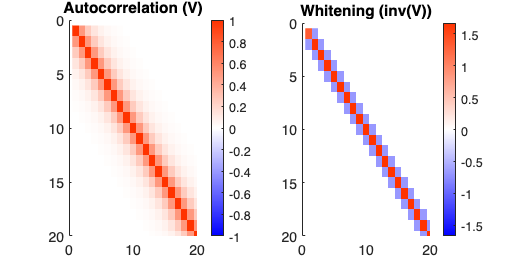

imagesc(V); colorbar
title('Autocorrelation (V)')
set(gca, 'YDir', 'Reverse'); axis tight
% zoom in
set(gca, 'XLim', [0 20], 'YLim', [0 20])
canlab_redblue_symmetric_colormap

subplot(1, 2, 2)
imagesc(inv(V))
title('Whitening (inv(V))')
colorbar
set(gca, 'YDir', 'Reverse'); axis tight
% zoom in
set(gca, 'XLim', [0 20], 'YLim', [0 20])
canlab_redblue_symmetric_colormap

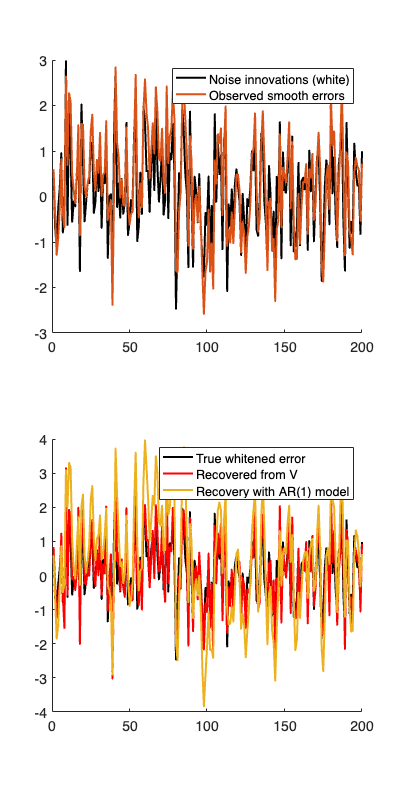


eta = randn(n, 1); % some data, the ideal whitened error timeseries.  where \epsilon(t) ~ N(0,\sigma^2) 
create_figure('e', 2, 1); 
plot(eta, 'k', 'LineWidth', 2)

% es = filter(1, [1 rho], eta); 

% manual generation: e(t) = \rho e(t-1) + \eta(t)
% etapad = [0; eta];
es(1) = eta(1);
for i = 2:length(eta)
    es(i) = rho * es(i - 1) + eta(i);
end


hold on; 
plot(es, 'LineWidth', 2)
legend({'Noise innovations (white)' 'Observed smooth errors'})

subplot(2, 1, 2);

plot(eta, 'k', 'LineWidth', 2) 

% plot(inv(sqrt(V)) * es, 'r', 'LineWidth', 2) % ideal whitened with true V matrix
% Note: sqrt(V) is different than V ^ 0.5 here

plot(inv(V ^ 0.5) * es, 'r', 'LineWidth', 2) % ideal whitened with true V matrix
% this is the same:
% plot((inv(V) ^ 0.5) * es, 'b', 'LineWidth', 2) % ideal whitened with true V matrix

% with noisy V estimate based on data - can we recover the true
% coefficient?
rho_hat = aryule(es, 1);

v_hat_vec = rho_hat(1);

for i = 2:n 

    v_hat_vec(i) = rho_hat(2) .^ (i-1); 

end
V_hat = toeplitz(v_hat_vec);

plot(inv(V_hat ^ 0.5) * es, 'LineWidth', 2) % recovered: whitened with estimated V matrix

legend({'True whitened error' 'Recovered from V' 'Recovery with AR(1) model'})

% see also:
%[xc,Vi] = canonical_autocorrelation(TR,n,varargin)